## *Chocó Map*

### 0. Preparing environment

#### 1. Clear command window, workspace variables, and close all figures. Turn off warnings.

clear; clc; close all;
warning('off', 'all');

#### 2. Set the path to the folder containing the layer data

layerfolder = 'data/layers/';

#### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 7.403727 seconds.


Samples = [20, 50, 100, 500];
CorrelationPercentages = [0.7, 0.8, 0.9];
metA = NaN(30,2);
metB = NaN(30,2);

for i=1:30


#### 1.1 Using Harmonic Method

InfoInitialPoint = InitialPoint(Layers,'harmonic', false);

### 2. Generate the niche map using niche generation algorithm with the initial point

MapInfo = NicheGeneration(Layers, InfoInitialPoint, 0.5, false);

### 3. Generate the samples in the map

sample = Samples(3);
T = samplingVS(Layers, InfoInitialPoint, MapInfo, sample, -1, false, 'GenSP', true, true);
corr = CorrelationPercentages(3);
frontierDepth = FrontierDepth(T,Layers,0,1,false,false,false);

Accuracy of the estimated niche

met = MapMetric(MapInfo.Map,frontierDepth.map,false);
metA(i,1) = met(1);
frontierDepth = FrontierDepth(T,Layers,1,1,false,false,false);
met = MapMetric(MapInfo.Map,frontierDepth.map,false);
metA(i,2) = met(1);

hFrontierDepth = HFrontierDepth(T,Layers,0,25,false,false,false); 
met = MapMetric(MapInfo.Map,hFrontierDepth.map,false);
metB(i,1) = met(1);
hFrontierDepth = HFrontierDepth(T,Layers,1,25,false,false,false); 
met = MapMetric(MapInfo.Map,hFrontierDepth.map,false);
metB(i,2) = met(1);
i
end

i = 1

mean(metA)

ans =     0.8302    0.7983


mean(metB)

ans =     0.7152    0.8031


met1 = NaN(5,100);
for i=1:5


#### 1.1 Using Harmonic Method

InfoInitialPoint = InitialPoint(Layers,'harmonic', false);

### 2. Generate the niche map using niche generation algorithm with the initial point

MapInfo = NicheGeneration(Layers, InfoInitialPoint, 0.5, false);

### 3. Generate the samples in the map

sample = Samples(3);
T = samplingVS(Layers, InfoInitialPoint, MapInfo, sample, -1, false, 'GenSP', true, true);
corr = CorrelationPercentages(3);

Accuracy of the estimated niche


frontierDepth = FrontierDepthTest(T,Layers,1,1,false,false,false,MapInfo);
met1(i,:) = frontierDepth.met;
i
end

i = 1

i = 2

i = 3

i = 4

i = 5

mean1=mean(met1)

mean1 =     0.7829    0.8154    0.8344    0.8466    0.8581    0.8672    0.8773    0.8837    0.8852    0.8826    0.8830    0.8792    0.8737    0.8622    0.8518    0.8355    0.8211    0.8058    0.7951    0.7860    0.7755    0.7654    0.7557    0.7451    0.7373    0.7258    0.7146    0.7079    0.7009    0.6940    0.6888    0.6827    0.6766    0.6698    0.6640    0.6593    0.6553    0.6504    0.6467    0.6430    0.6388    0.6352    0.6315    0.6287    0.6262    0.6232    0.6194    0.6159    0.6129    0.6096


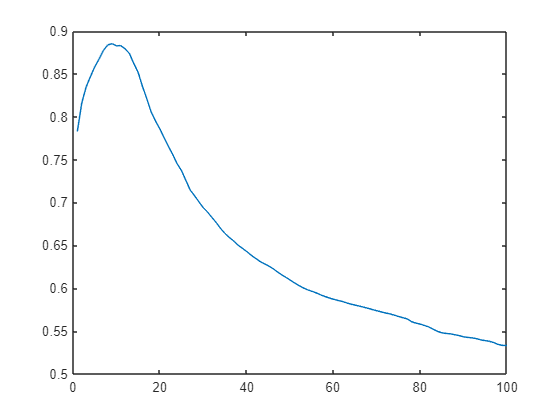

plot(1:100, mean1)

#### Frontier Depth

Frontier Depth `generates a niche probability intensity map, by using the depth of each sample to the samples 3d hull.`

`Estimation = FrontierDepth(SamplePoints,Dimensions,shrinking factor,percent,show,outlier1,outlier2)`

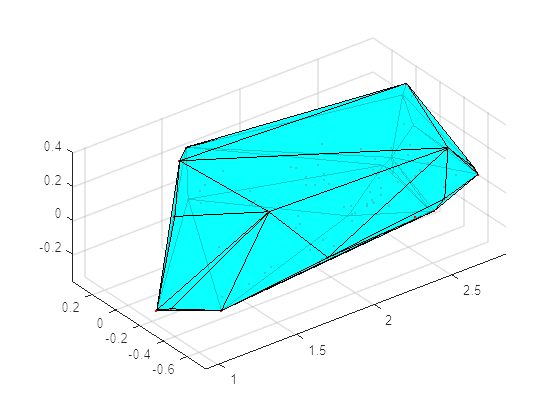

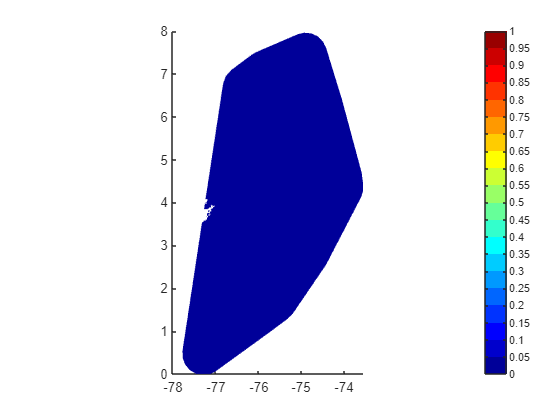

%percentile = percentile 
% with which the radius will be taken
percentile = 25;

Estimation1 = FrontierDepth(T,Layers,0,1,show,outlier1,outlier2); 

Accuracy of the estimated niche

MapMetric(MapInfo.Map,Estimation1.map,false)

ans =     0.6716    0.5993
